# Automatic Indentification of Glaucoma Using Deep Learning Methods

#### By Allan Cerentini

*Architecture****: *****Transfer Leanring **

                     **Pretrained GoogLeNet **

*Preprocessing****: *****Resize image to 224*224**

*DataSet**** : *****RIM-ONE V2**

                **Total Image Count: 455**

**                Normal Images: 255**

*Author:* **Gyanendar Manohar (R00207241)**

*Date:**** 27/02/2022***

***==========================================================================================***

### Set Random Seed

rng(49)

### Load Dataset


image_data_store = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIMONE-db-r2','IncludeSubfolders',true,'LabelSource','foldernames');
[x_train_ds,x_test_ds] = splitEachLabel(image_data_store,0.9,'randomized');
numClasses = numel(categories(x_train_ds.Labels))

numClasses = 2

### GoogLeNet

googLe_net = googlenet;
input_size = googLe_net.Layers(1).InputSize

input_size =    224   224     3


### Augment Image

resized_train = augmentedImageDatastore(input_size(1:2),x_train_ds);
resized_test  = augmentedImageDatastore(input_size(1:2),x_test_ds);

# Transfer Larening

### Replace top layer


googLe_layer_graph = layerGraph(googLe_net); 

new_fully_connected_layers = fullyConnectedLayer(numClasses, 'Name','new_fc', ...
                            'WeightLearnRateFactor',0.1,'BiasLearnRateFactor',0.1);


replaced_layer_graph = replaceLayer(googLe_layer_graph,'loss3-classifier',new_fully_connected_layers);

### Make Final

newClassLayer = classificationLayer('Name','new_classoutput');
final_graph = replaceLayer(replaced_layer_graph,'output',newClassLayer);

### Freez Initial Weights

layers = final_graph.Layers;
connections = final_graph.Connections;
layers(1:10) = freezeWeights(layers(1:10));
final_graph = createLgraphUsingConnections(layers,connections);

### Train Network

rim_one_r2_final_graph = final_graph

rim_one_r2_final_graph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_classoutput'}


rim_one_dl_final_graph = final_graph

rim_one_dl_final_graph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_classoutput'}


acrima_final_graph = final_graph

acrima_final_graph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_classoutput'}


### FineTuning

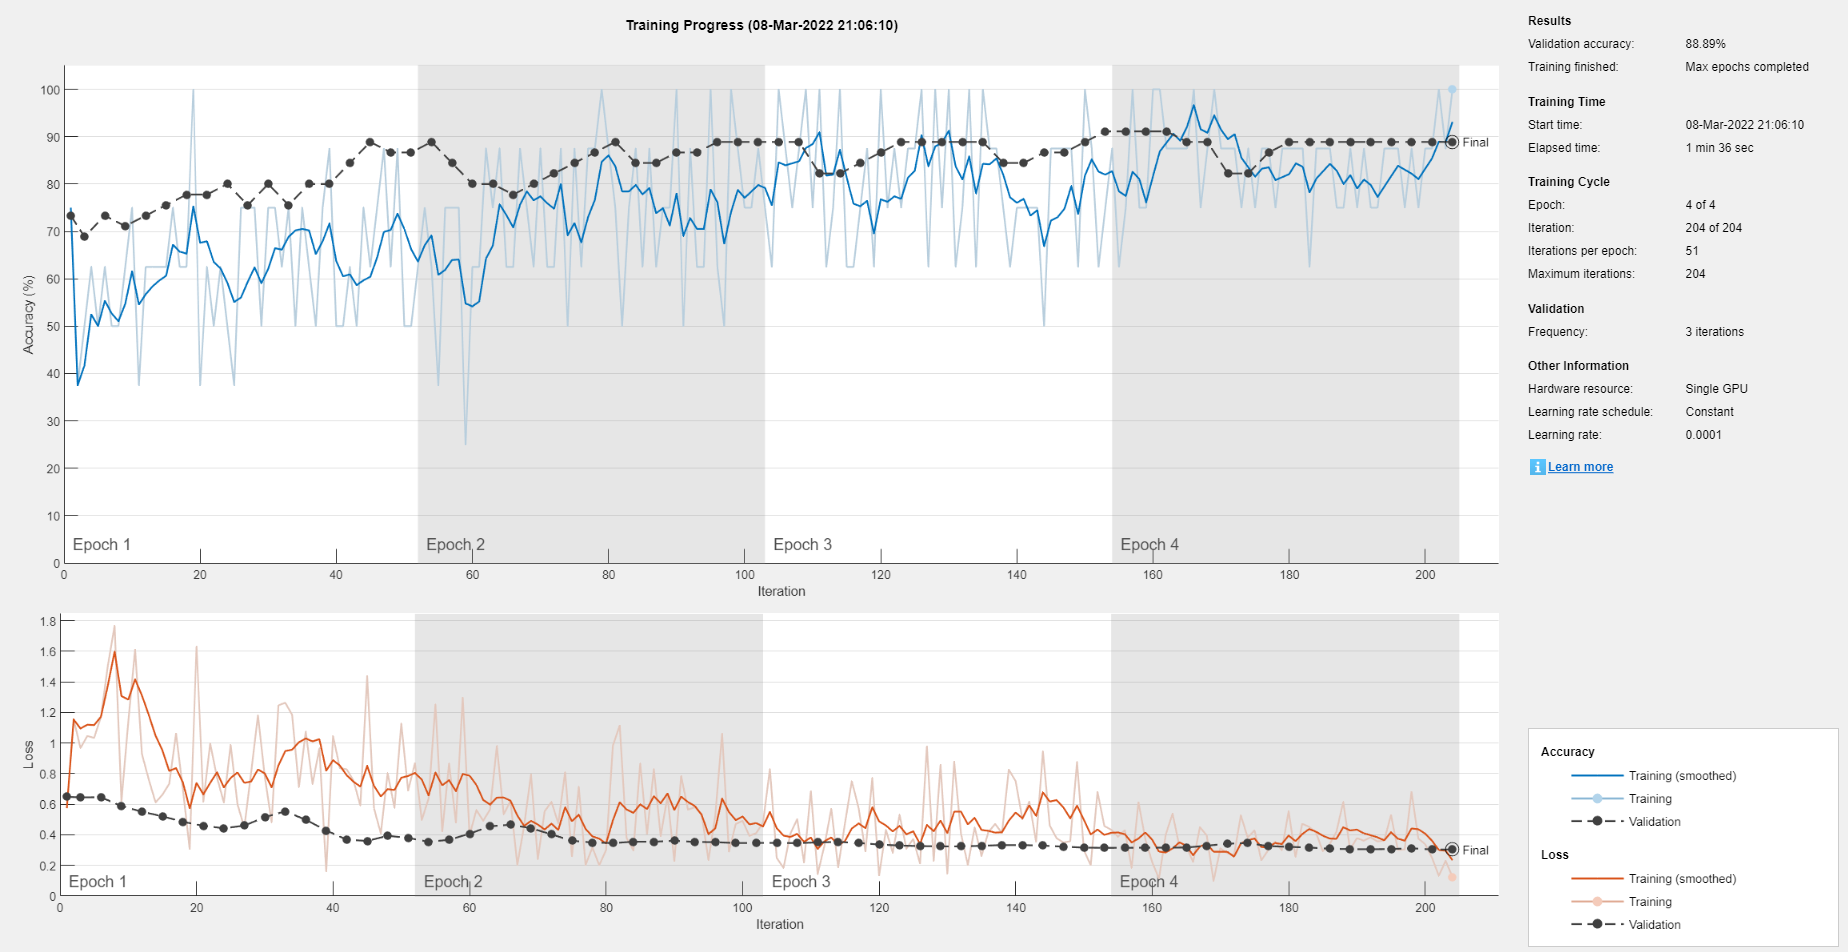

options = trainingOptions('sgdm', ...
    'MiniBatchSize',8, ...
    'MaxEpochs',4, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',resized_test, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

trained_model = trainNetwork(resized_train,rim_one_r2_final_graph,options);

### Validation Accuracy

[y_predicted,probs] = classify(trained_model,resized_test);
accuracy = mean(y_predicted == x_test_ds.Labels)

accuracy = 0.8889

### Confusion Chart

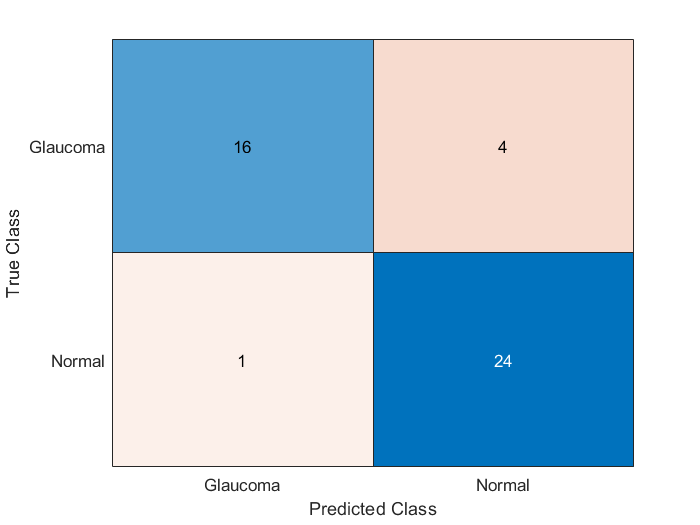

confusionchart(x_test_ds.Labels,y_predicted)

[conf_matrix,order] = confusionmat(x_test_ds.Labels,y_predicted)

conf_matrix =     16     4
     1    24


order = 2×1 categorical array
     Glaucoma 
     Normal 


tp = conf_matrix(1,1)

tp = 16

tn = conf_matrix(2,2)

tn = 24

fn = conf_matrix(1,2)

fn = 4

fp = conf_matrix(2,1)

fp = 1

### Sensitivity

sensitivity = tp/(tp+fn)

sensitivity = 0.8000

### Specificity

specificity = tn/(tn+fp)

specificity = 0.9600

# RIM-ONE-DL

### Set Random Seed

rng(49)

### Load Dataset

rimone_dl_data_store_train = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIM-ONE_DL_images\partitioned_randomly\training_set','IncludeSubfolders',true,'LabelSource','foldernames');
rimone_dl_data_store_test = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIM-ONE_DL_images\partitioned_randomly\test_set','IncludeSubfolders',true,'LabelSource','foldernames');

### Resize Image to match the input size

rim_one_dl_aug_train = augmentedImageDatastore([224 224],rimone_dl_data_store_train);
rim_one_dl_aug_test = augmentedImageDatastore([224 224],rimone_dl_data_store_test);

### Train and Test labels

rimone_dl_y_train = double(categorical(rimone_dl_data_store_train.Labels));
rimone_dl_y_test = double(categorical(rimone_dl_data_store_test.Labels));

### Train

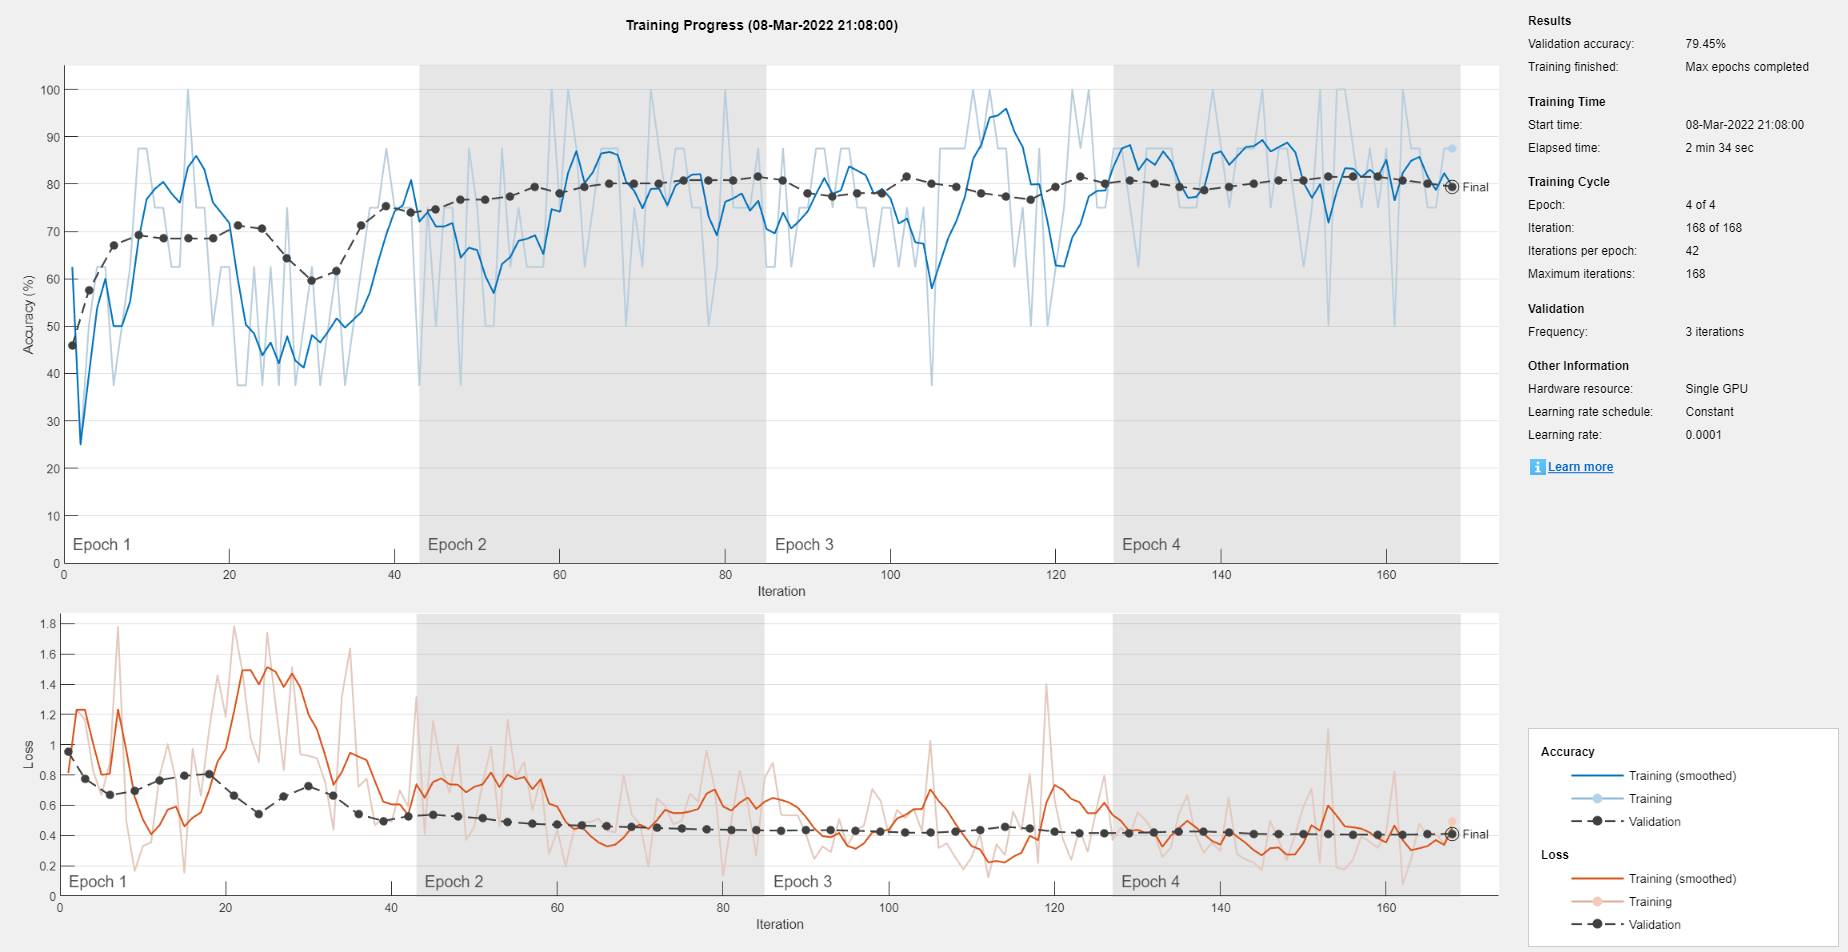

rimone_dl_options = trainingOptions('sgdm', ...
    'MiniBatchSize',8, ...
    'MaxEpochs',4, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',rim_one_dl_aug_test, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');
rim_1_dl_trained_model = trainNetwork(rim_one_dl_aug_train,rim_one_dl_final_graph,rimone_dl_options);

### Validation Accuracy

[rimone_dl_y_predicted,rim_1_probs] = classify(rim_1_dl_trained_model,rim_one_dl_aug_test);
rimone_dl_accuracy = mean(rimone_dl_y_predicted == rimone_dl_data_store_test.Labels)

rimone_dl_accuracy = 0.7945

### Confusion Chart

confusionchart(rimone_dl_data_store_test.Labels,rimone_dl_y_predicted)

### Confusion Matrix

[rim_one_dl_conf_matrix,rim_one_dl_order] = confusionmat(rimone_dl_data_store_test.Labels,rimone_dl_y_predicted)

rim_one_dl_conf_matrix =     36    16
    14    80


rim_one_dl_order = 2×1 categorical array
     glaucoma 
     normal 


rim1dl_tp = rim_one_dl_conf_matrix(1,1)

rim1dl_tp = 36

rim1dl_tn = rim_one_dl_conf_matrix(2,2)

rim1dl_tn = 80

rim1dl_fn = rim_one_dl_conf_matrix(1,2)

rim1dl_fn = 16

rim1dl_fp = rim_one_dl_conf_matrix(2,1)

rim1dl_fp = 14

### Sensitivity

rim1dl_sensitivity = rim1dl_tp/(rim1dl_tp+rim1dl_fn)

rim1dl_sensitivity = 0.6923

### Specificity

rim1dl_specificity = rim1dl_tn/(rim1dl_tn+rim1dl_fp)

rim1dl_specificity = 0.8511

# ACRIMA

### Set Random Seed

rng(49)

### Load Dataset

acrima_image_data_store = imageDatastore('C:\gyani\Projects_MS\code\dataset\ACRIMA_dataset\Database','IncludeSubfolders',true,'LabelSource','foldernames');
[acrima_x_train_ds,acrima_x_test_ds] = splitEachLabel(acrima_image_data_store,0.9,'randomized');
acrima_numClasses = numel(categories(acrima_x_train_ds.Labels))

acrima_numClasses = 2

### Resize Image to match the input size

acrima_aug_train = augmentedImageDatastore([224 224],acrima_x_train_ds);
acrima_aug_test = augmentedImageDatastore([224 224],acrima_x_test_ds);

### Train and Test labels

acrima_y_train = double(categorical(acrima_x_train_ds.Labels));
acrima_y_test = double(categorical(acrima_x_test_ds.Labels));

### Train

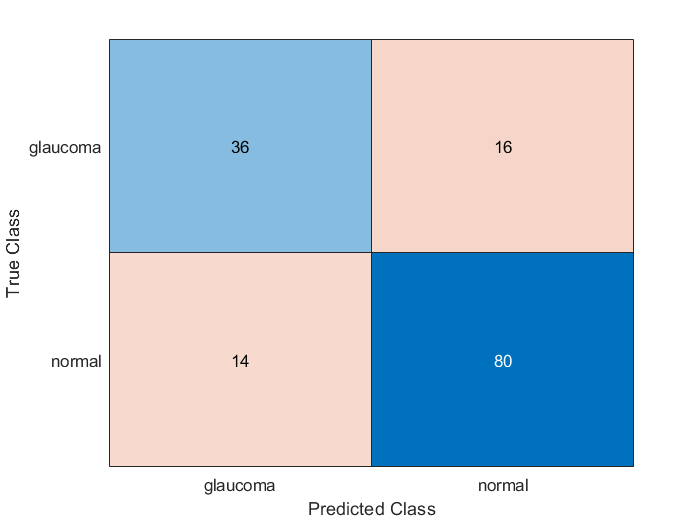

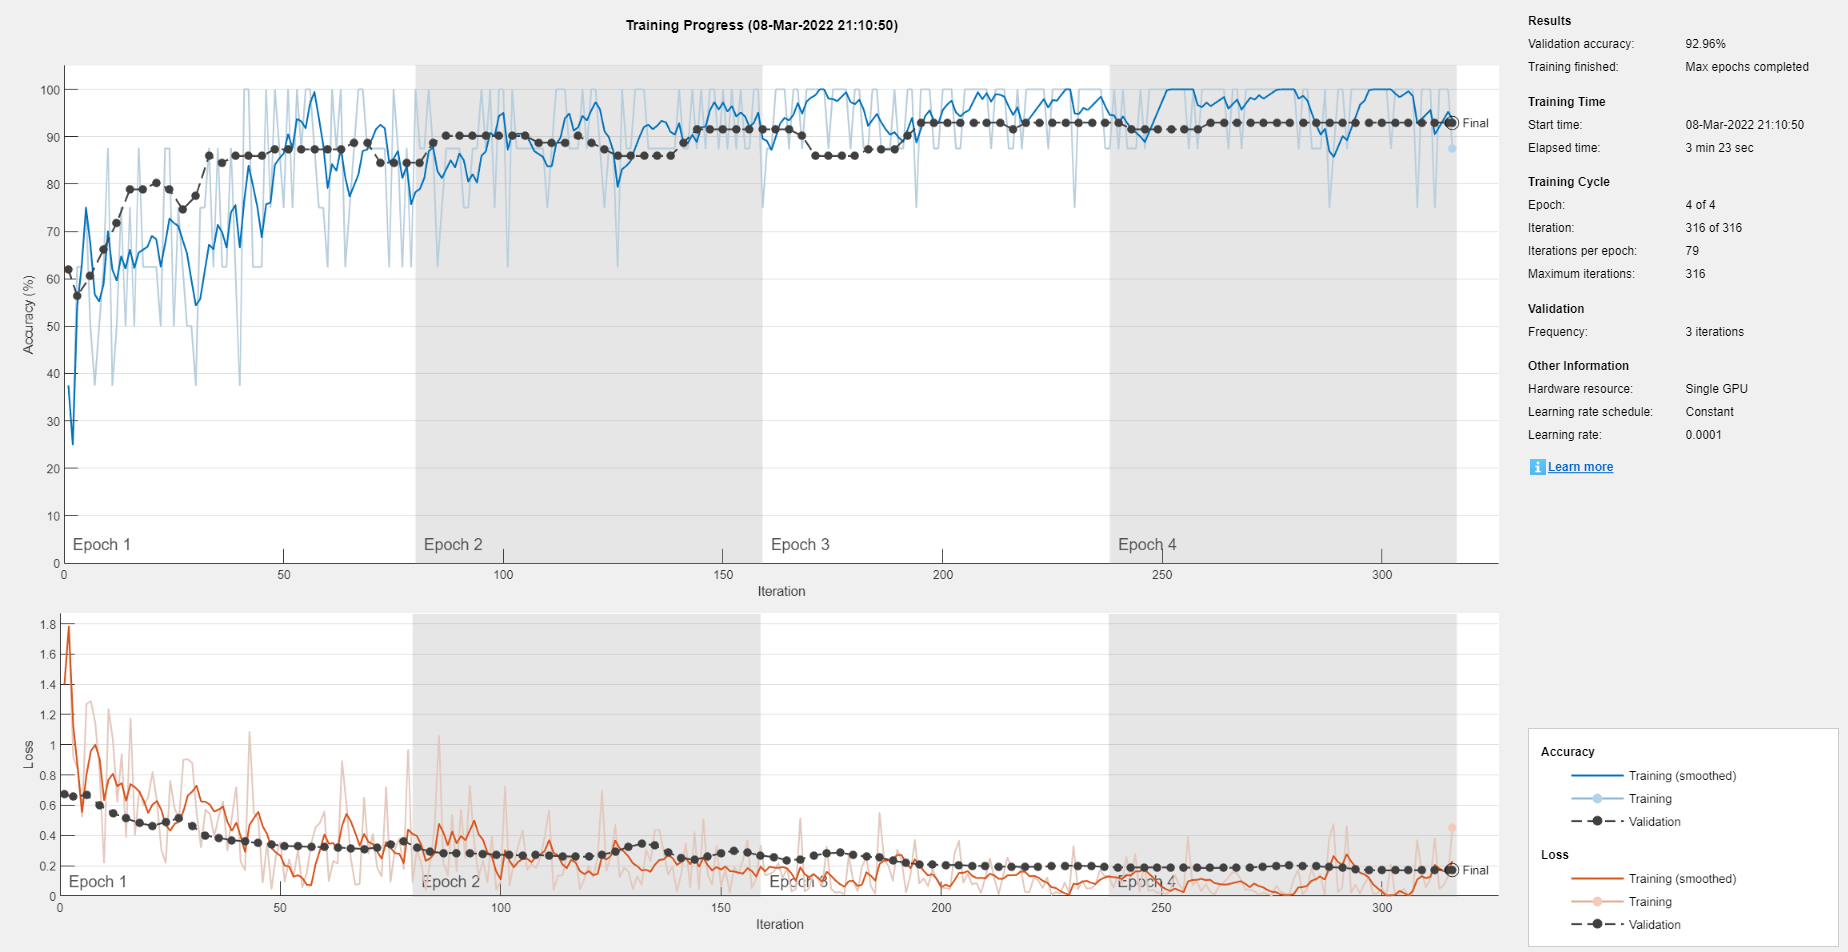

acrima_options = trainingOptions('sgdm', ...
    'MiniBatchSize',8, ...
    'MaxEpochs',4, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',acrima_aug_test, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');
acrima_trained_model = trainNetwork(acrima_aug_train,acrima_final_graph,acrima_options);

### Validation Accuracy

[acrima_y_predicted,acrima_probs] = classify(acrima_trained_model,acrima_aug_test);
acrima_accuracy = mean(acrima_y_predicted == acrima_x_test_ds.Labels)

acrima_accuracy = 0.9296

### Confusion Chart

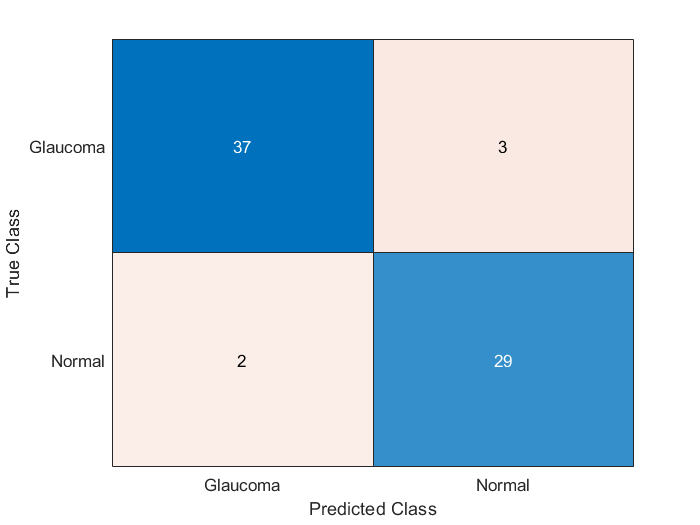

confusionchart(acrima_x_test_ds.Labels,acrima_y_predicted)

### Confusion Matrix

[acrima_conf_matrix,acrima_order] = confusionmat(acrima_x_test_ds.Labels,acrima_y_predicted)

acrima_conf_matrix =     37     3
     2    29


acrima_order = 2×1 categorical array
     Glaucoma 
     Normal 


acrima_tp = acrima_conf_matrix(1,1)

acrima_tp = 37

acrima_tn = acrima_conf_matrix(2,2)

acrima_tn = 29

acrima_fn = acrima_conf_matrix(1,2)

acrima_fn = 3

acrima_fp = acrima_conf_matrix(2,1)

acrima_fp = 2

### Sensitivity

acrima_sensitivity = acrima_tp/(acrima_tp+acrima_fn)

acrima_sensitivity = 0.9250

### Specificity

acrima_specificity = acrima_tn/(acrima_tn+acrima_fp)

acrima_specificity = 0.9355